%import
clear
clc
path = 'C:\Users\thamr\OneDrive\Desktop\finalMatlab\dataset-3atest.xlsx';
Q1a = readmatrix(path,'Sheet','Q1A');
QHS1 = readmatrix(path,'Sheet','QH_S1');
QHS3 = readmatrix(path,'Sheet','QH_S3');

%Q ที่สถานี S3 (M7) โดยใช้ค่า Q ที่สถานี S1 และ S2 ระหว่าง Day 1 และ Day 60 
qData1 = Q1a(:,3);
qData2 = Q1a(:,4);
qData1 = qData1(~isnan(qData1));
qData2 = qData2(~isnan(qData2));
qData3 = qData2+qData1;

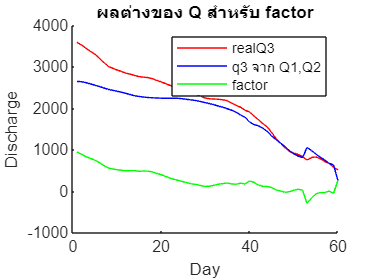

%factor ที่เกิดขึ้น เมื่อเปรียบเทียบกับข้อมูล Q จริง 
realData3 = Q1a(:,5);
realData3 = realData3(~isnan((realData3)));
factor = realData3 - qData3;
day = 1:length(factor);
hold on
plot(day,realData3,Color='r');
plot(day,qData3,Color='b');
plot(day,factor,Color='g');
xlabel("Day")
ylabel("Discharge")
title("ผลต่างของ Q สำหรับ factor")
legend("realQ3","q3 จาก Q1,Q2","factor")
hold off


xlswrite(path,factor,1,'F2');